Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# Pill-box explorer for TM modes(Section 5.1)

Volker Ziemann, 211122, CC-BY-SA-4.0

In this example we display the longitudinal elelctric field $E_z$ of a $T_{mn0}$ mode in a pill-box cavity for values of $m$ and $n$ of up to $5$. 

For the radius of the cavity $R_{cav}$ we assume the value of 1 m.

clear all;
Rcav=1;

We  use sliders to select the values of $m$ (order of the Bessel function or number of azimuthal zeros)  and $n$, the number of the zero.

m=1;   % Slider to select m in J_m
n=2;   % Slider to select n-th zero

The longitudinal electric field is then given by Equation 5.21, where $J_m(k_cR_{cav})$ must be zero on the metallic boundary, which requires $\gamma_{mn}=k_cR_{cav}$ to be a zero of the $m$-th Bessel function $J_m$. Following the suggestion from "Matlab Answers" ([https://se.mathworks.com/matlabcentral/answers/230834-zeros-of-bessel-functions](https://se.mathworks.com/matlabcentral/answers/230834-zeros-of-bessel-functions)) we first roughly estimate where the zero is and then use the function `fzero()` to find it accurately. 

guess = 2.5505 + 1.2474*m + (n-1)*pi;       % From "Matlab Answers"
gamma_mn=fzero(@(x)besselj(m,x),guess)      % n-th zero of m-th Bessel function J_m

gamma_mn = 7.0156

In the next step we define a radial meshgrid and determine the longitudinal electric field $E_z$ on the gridpoints.

r=0.0:0.02:1;                               % radial grid points
phi=0:pi/20:2*pi;                           % angular grid points
[R,PHI]=meshgrid(r,phi);                    % make meshgrid
Ez=besselj(m,gamma_mn*R/Rcav).*cos(m*PHI);  % Ez/E0

Finally, we plot the field as a surface plot with a contour map shown below.

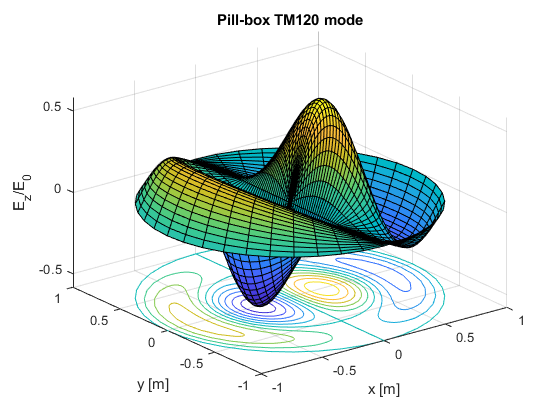

surfc(R.*cos(PHI),R.*sin(PHI),Ez)
xlabel('x [m]'); ylabel('y [m]'); zlabel('E_z/E_0')
title(['Pill-box TM',num2str(m),num2str(n),'0 mode'])